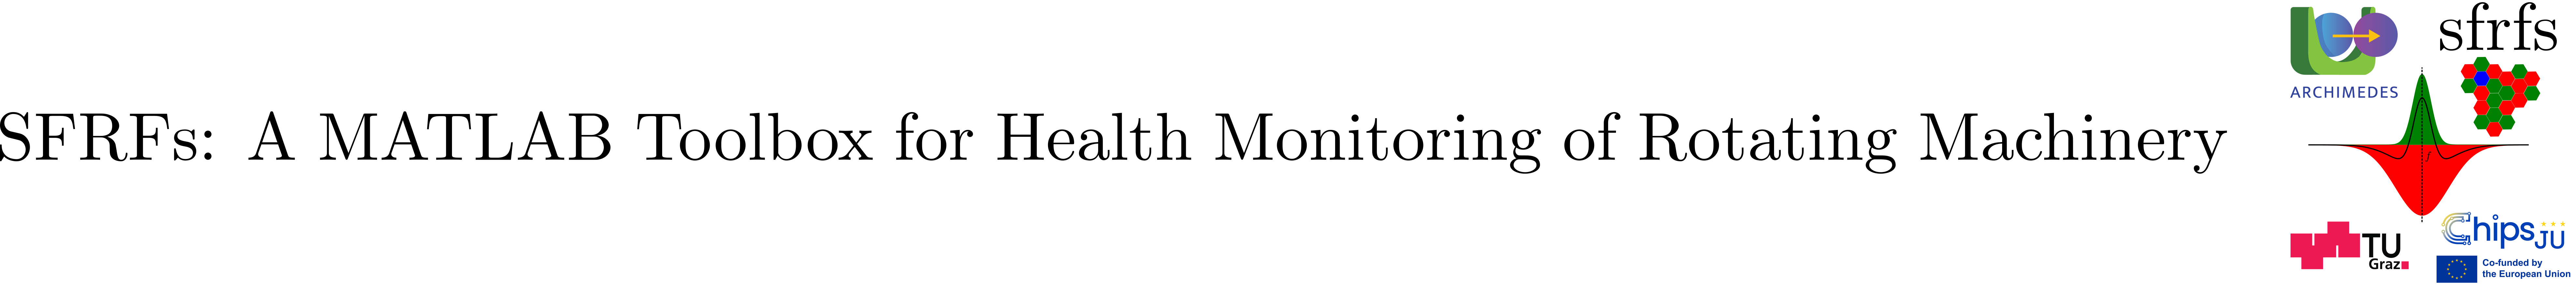

# ContrastMappings

## Summary

Standard library of contrast mappings for center-surround opponency. 

Each static method returns a function handle `map` that computes contrast from center and surround responses.

## Description

ContrastMappings defines a collection of static factory methods that generate contrast mapping functions for center–surround opponency. Each factory returns a function handle that combines center responses and surround responses into a contrast response according to a specific mapping rule.

### Public static methods

- `map = ContrastMappings.difference(k = k)`

- `map = ContrastMappings.ratio(k = k, eps = eps)`

- `map = ContrastMappings.logRatio(k = k, eps = eps)`

- `map = ContrastMappings.normalizedDifference(k = k, eps = eps)`

Defaults: `k = 1`, `eps = 1e-12` (where applicable). `eps` must be positive.

#### Returned handle signature

- `c = map(Rc, Rs)`

- `c = map(Rc, Rs, params)`

`params` is optional; if provided it must be a **scalar struct** (or empty). If `params.k` or `params.eps` are present and nonempty, they override the factory defaults.

#### Inputs/Output

- `Rc`: center response (scalar or vector)

- `Rs`: surround response (same size as `Rc`)

- `c`: contrast value(s), same size as `Rc`/`Rs`

#### Definitions

- `difference`: `Rc - k.*Rs`

- `ratio`: `Rc ./ (k.*Rs + eps)`

- `logRatio`: `log((Rc + eps) ./ (k.*Rs + eps))`

- `normalizedDifference`: `(Rc - k.*Rs) ./ (Rc + k.*Rs + eps)`

#### Validation / errors

- `params` must be a scalar struct (or empty), else `sfrfs:ContrastMappings:InvalidParams`.

- overridden `eps` must be positive finite scalar, else `sfrfs:ContrastMappings:InvalidEps`.

### Notes

- Contrast mappings are parameterized by an inhibition factor specified at construction time or overridden at evaluation time via a scalar parameter structure. 

- The stabilization constant is used solely to ensure numerical robustness.

### See also

[CenterSurroundCompute](matlab:open('./CenterSurroundCompute.mlx')), [ReceptiveFieldResponseFunctions](matlab:open('./ReceptiveFieldResponseFunctions.mlx')), [ReceptiveFieldGainFunctions](matlab:open('./ReceptiveFieldGainFunctions.mlx')), [FrequencyMask](matlab:open('./FrequencyMask.mlx'))

## Example

% Inhibition factor
k = 0.8;

% Define contrast mappings
maps = { ...
    ContrastMappings.difference(k = k), ...
    ContrastMappings.ratio(k = k, eps = 1e-10), ...
    ContrastMappings.logRatio(k = k, eps = 1e-10), ...
    ContrastMappings.normalizedDifference(k = k, eps = 1e-10)};

mapNames = [ ...
    "(difference)"; ...
    "(ratio)"; ...
    "(log-ratio)"; ...
    "(normalized difference)"];

% Scalar center and surround responses
Rc = 1.2;
Rs = 0.7;

% Evaluate all contrast mappings
for i = 1:numel(maps)
    c = maps{i}(Rc, Rs);
    fprintf("%s : %.4f\n", mapNames(i), c);
end

(difference) : 0.6400
(ratio) : 2.1429
(log-ratio) : 0.7621
(normalized difference) : 0.3636


## API documentation

### MATLAB help

help ContrastMappings

 ContrastMappings  A standard library of contrast mappings for 
  center-surround opponency.
  Each static method returns a function handle callable as:
    c = map(Rc, Rs)
    c = map(Rc, Rs, params)
 
  Inputs:
    Rc     - center response (scalar or vector)
    Rs     - surround response (same size as Rc)
    params - optional scalar struct with mapping parameters. Fields depend
             on the mapping; unused fields are ignored.
 
  Output:
    c      - contrast value(s), same size as Rc/Rs.
 
  Usage note:
    Mapping handles may optionally accept a third input argument for
    parameterization. How parameters are bound or provided is left to the
    mapping implementation.

    Documentation for ContrastMappings



## Source code

The source of the class can be found in [ContrastMappings](matlab:open('../../ContrastMappings.m')).

## Test

The unit test for this class can be found in [TestContrastMappings](matlab:open('../../../tests/TestContrastMappings.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestContrastMappings');

Running TestContrastMappings
........
Done TestContrastMappings
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestContrastMappings/testFactoriesReturnFunctionHandles                          | Passed
TestContrastMappings/testDifferenceScalarEvaluation                              | Passed
TestContrastMappings/testRatioScalarEvaluation                                   | Passed
TestContrastMappings/testLogRatioScalarEvaluation                                | Passed
TestContrastMappings/testNormalizedDifferenceScalarEvaluation                    | Passed
TestContrastMappings/testOverrideParamsAtEvaluationTime                          | Passed
TestContrastMappings/testInvalidParamsThrows                                     | Passed
TestContrastMappings/testInvalidEpsThrows                                        | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).